# HW2 Gabriel Colangelo

close all
clear all
clc

## Problem 1

% Problem 1 A Matrix
A_1             = @(x) [0 1;(1 - 3*x(1,1)^2) -0.1];

% Equilibrium States
xe1             = [0;0];
xe2             = [1;0];
xe3             = [-1;0];

% Eigenvalues
disp('Eigenvalues for x_e(1)')

Eigenvalues for x_e(1)


disp(eig(A_1(xe1)))

   -1.0512
    0.9512



disp('Eigenvalues for x_e(2)')

Eigenvalues for x_e(2)


disp(eig(A_1(xe2)))

  -0.0500 + 1.4133i
  -0.0500 - 1.4133i



disp('Eigenvalues for x_e(3)')

Eigenvalues for x_e(3)


disp(eig(A_1(xe3)))

  -0.0500 + 1.4133i
  -0.0500 - 1.4133i



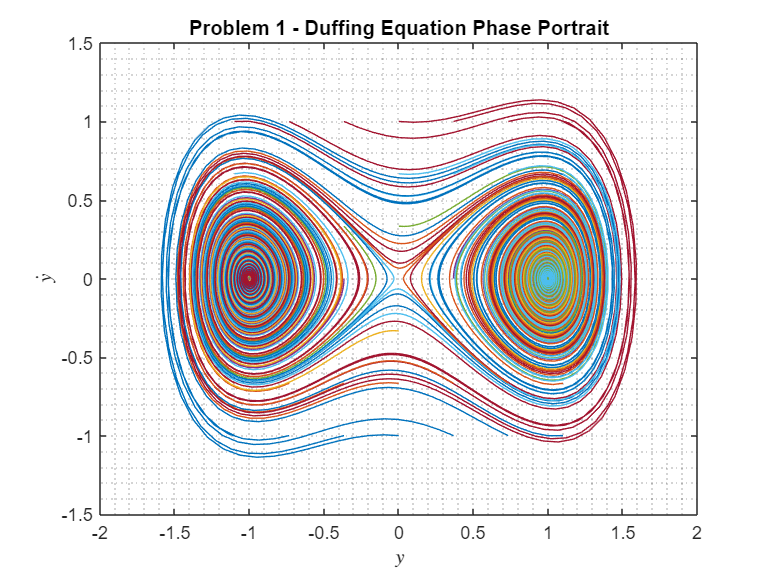

% sim time
time            = (0:.1:80)';

% ODE45 solver options
options         = odeset('AbsTol',1e-8,'RelTol',1e-8);

% Initial Conditions to loop through 
y_IC            = linspace(-1.1,1.1,7);
ydot_IC         = linspace(-1,1,7);

[IC_x,IC_y]     = meshgrid(y_IC,ydot_IC);
IC              = [IC_x(:)';IC_y(:)'];

% Initialize vectors
y               = zeros(length(time),length(IC));
ydot            = y;

for i = 1:length(IC)
    % ODE45 Function call
    [~, X]      = ode45(@(t,x) Duffing(t,x), time, IC(:,i), options);

    % Extract and Store States
    y(:,i)      = X(:,1);
    ydot(:,i)   = X(:,2);
end

figure
plot(y,ydot)
grid minor
ylabel('$\dot{y}$','Interpreter','latex')
xlabel('$y$','Interpreter','latex')
title('Problem 1 - Duffing Equation Phase Portrait')

## Problem 2

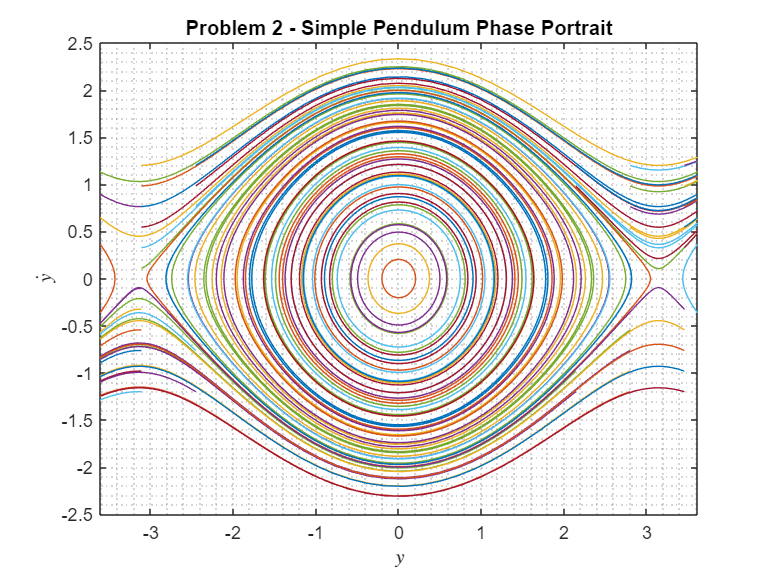

% Sim time
pend_t                  = 0:.1:50;

% Pendulum Equilibrium States
pend_xe1                = [0;0];
pend_xe2                = [pi;0];

% Initial Conditions to loop through 
pend_y_IC               = linspace(-1.2*pi,1.1*pi,12);
pend_ydot_IC            = linspace(-1.2,1.2,12);

[pend_IC_x,pend_IC_y]   = meshgrid(pend_y_IC,pend_ydot_IC);
pend_IC                 = [pend_IC_x(:)';pend_IC_y(:)'];

% Initialize vectors
pend_y                  = zeros(length(pend_t),length(pend_IC));
pend_ydot               = pend_y;

for i = 1:length(pend_IC)
    % ODE45 Function call
    [~, X]          = ode45(@(t,x) SimplePendulum(t,x),...
                            pend_t, pend_IC(:,i), options);

    % Extract and Store States
    pend_y(:,i)     = X(:,1);
    pend_ydot(:,i)  = X(:,2);
end

figure
plot(pend_y,pend_ydot)
xlim([-1.15*pi 1.15*pi])
grid minor
ylabel('$\dot{y}$','Interpreter','latex')
xlabel('$y$','Interpreter','latex')
title('Problem 2 - Simple Pendulum Phase Portrait')

## Functions

function xdot = Duffing(t,x)
xdot(1,1)   = x(2,1);
xdot(2,1)   = -0.1*x(2,1) + x(1,1) - x(1,1)^3;

end

function xdot = SimplePendulum(t,x)
xdot(1,1)   = x(2,1);
xdot(2,1)   = -sin(x(1,1));
end